# Vogel_Max_DifferentialEquations

This script builds on DifferentialEquations.mlx to solve for ballistic motions in 2 dimensions with quadratic drag.

Author: Max Vogel

a.) Ballistic Trajectory

b.) Energy

c.) Varying Launch Angles

d.) Ideal Launch Angle

## Euler method of integration

clear;delete(findall(0,'Type','figure'))% close all open figure windows

Set number of steps `N` in the time range.

N=100;

We will numerically step the mass through a trajectory, computing and updating the velocity and position along the way, and after we are done, plot the results.

Declare global variables common to the main code to share with a function `V_t `given below. We initialize them here and could change the values globally. We'll reference Wikipedia for the [Golf ball's statistics](https://en.wikipedia.org/wiki/Golf_ball) as well as for [Atmospheric pressure](https://en.wikipedia.org/wiki/Atmospheric_pressure).

% Set initial conditions for the calculation. Let's launch the mass with a 45 degree angle from the origin of displacements. 
global gx gz m d r xsec c rho;

gx=0; % no initial resistance in x direction
gz=-10.0; % gravity
tmin = 0; tmax = 14; % a range of times

m = .0455; % kg
d = .0427; % m
r = d/2;
% vol = 4/3 * pi * r^3; 
xsec = pi * r^2; %crossectional area
c = 0.2; % drag coef
rho = 1.2041; % kg/m³ at 70 degrees F


We'll then prepare a fixed vector of discrete times and initialize cooresponding vectors of values for acceleration, velocity, and position in the x and z components.

v0net = 67.056; % m/s
angle = pi/4; % radians above horizon
vx0=v0net*cos(angle);%initial xcomponent
vz0=v0net*sin(angle);%initial ycomponent
x0=0;z0=0.0;% initial velocity and position

t=linspace(tmin,tmax, N);% make a vector of time values
dt=t(2)-t(1);% time increment

global x z;
ax= zeros(1,numel(t));% preallocate vector of acceleration values
vx= zeros(1,numel(t));% preallocate vector of velocity values
x= zeros(1,numel(t));% preallocate vector of position values

az= zeros(1,numel(t));% preallocate vector of acceleration values
vz= zeros(1,numel(t));% preallocate vector of velocity values
z= zeros(1,numel(t));% preallocate vector of position values

We can then set initial values

ax(1)=0;
az(1)= gz;%initialize

vx(1)=vx0;
vz(1)=vz0;%initialize

x(1)=x0;
z(1)=z0;%initialize

We can then calculate our trajectory by iterating through in steps of dt

for i=2:N 
    V=[vx(i-1);vz(i-1);x(i-1);z(i-1)];
    a= V_t(t(i-1),V); % compute acceleration with user function
    ax(i)=a(1);
    az(i)=a(2);
    vx(i)= vx(i-1)+ax(i-1)*dt;
    vz(i)= vz(i-1)+az(i-1)*dt;
    x(i)= x(i-1)+vx(i-1)*dt+(1/2)*ax(i-1)*dt^2;
    z(i)= z(i-1)+vz(i-1)*dt+(1/2)*az(i-1)*dt^2;    

We'll exit the loop via break of we have returned to the horizontal.

    if z(i)<0 && x(i)>0
        M=i-1;
        break
    end
end

Since we don't always stop at the same indice, we'll trim extra entries in the arrays.

t=t(1:M); x=x(1:M); z=z(1:M); vx=vx(1:M); vz=vz(1:M); ax=ax(1:M); az=az(1:M);

and plot the trajectory

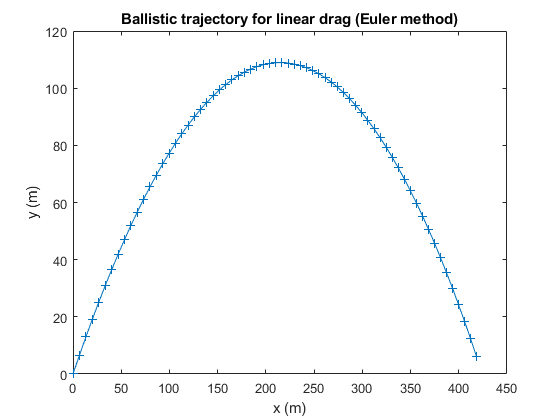

plot(x,z,'+-')
xlabel('x (m)');ylabel('y (m)');
title('Ballistic trajectory for linear drag (Euler method)')

Plot vertical position, velocity, and acceleration versus time including a symbol so we can see the time steps.

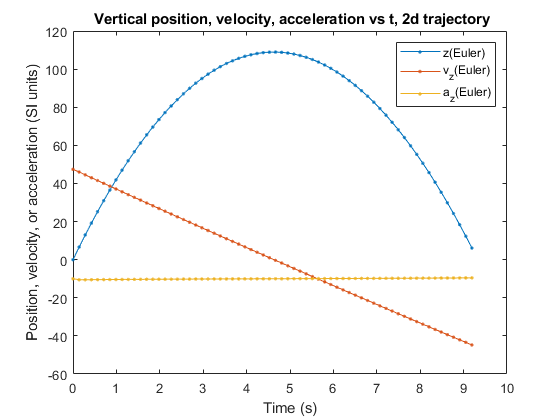

figure
plot(t,z,'.-')
xlabel('Time (s)')
ylabel('Position, velocity, or acceleration (SI units)')
hold on
plot(t,vz,'.-')
plot(t,az,'.-')
title(' Vertical position, velocity, acceleration vs t, 2d trajectory')
legend('z(Euler)','v_z(Euler)','a_z(Euler)')

## Symbolic Analytic Solutions

syms Z(T) V(T) RHO G V0 Z0 XSEC VX VZ C
ode = diff(V, T) == G - ((1/2) * C * RHO * XSEC * abs(V) * V);
cond = V(0) == V0;
vSolution(T) = dsolve(ode,cond);

ode = diff(Z,T) == vSolution(T);
cond = Z(0) == Z0;
zSolution(T) = dsolve(ode, cond);

d = .0427; % m
r = d/2;
xsec = pi * r^2;
c = 0.2;
rho = 1.2041; % kg/m³ at 70 degrees F

vS= subs(vSolution, V0, vz0);
vS= subs(vS, Z0, z0); vS= subs(vS, RHO, rho); vS= subs(vS, G, gz); 
vS= subs(vS, XSEC, xsec); vS= subs(vS, C, c);

## Energy

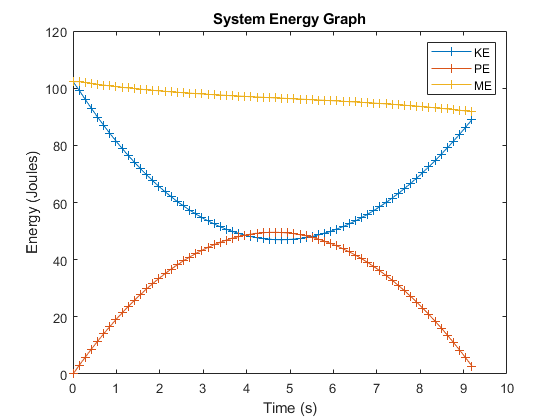

n = length(vx);
kinetic = zeros(n, 1); % preallocate/fill
potential = zeros(n, 1); % preallocate/fill
mechanical = zeros(n, 1); % preallocate/fill
velocity = zeros(n, 1); % preallocate/fill

vxrot = vx';
vzrot = vz';
zrot = z';


for i=1:n
    velocity(i) = sqrt(vxrot(i)^2 + vzrot(i)^2);
    kinetic(i) = 1/2* m * (velocity(i))^2;
    potential(i) = m * 10 * zrot(i);
    mechanical(i) = kinetic(i) + potential(i);
end


figure
plot(t,kinetic,'+-')
xlabel('Time (s)')
ylabel('Energy (Joules)')
hold on;
plot(t,potential,'+-')
plot(t,mechanical,'+-')
title('')
legend('KE','PE','ME')
title('System Energy Graph')
hold off;

## Various Angles

We'll setup our graph

figure;
xlabel('Time (s)');
ylabel('Distance (meters)');
title('Various Angle Ballistics Graph');
ylim([0 inf])
hold on;

as well as constants

x0 = 0;
z0 = 0;
g = 9.81;%m/s^2
angles = 5:5:85; % generates array of angles, starting from 5, skipping  every 10, stopping at 85
trange = [tmin,tmax];

angleRange = zeros(2, length(angles));

Then we can then iterate through and plot each value on our graph we established before

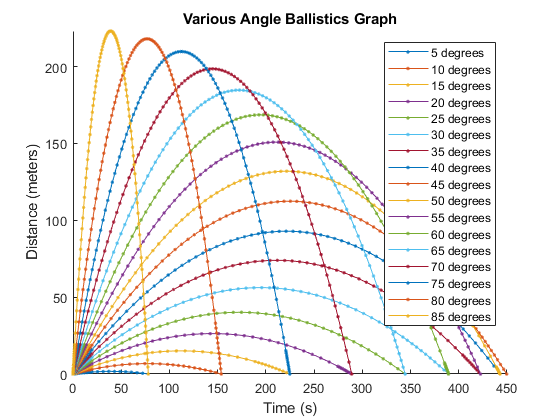

for i=1:length(angles)
    angle = angles(i); % gets angle from array
    vx0 = v0net * cosd(angle);
    vz0 = v0net * sind(angle);

    options=odeset('Events',@bounceEvents,'Refine',10);
    [Tode, Vode,te,ye,ie]=ode45(@V_t_noresistance,trange,[vx0,vz0,x0,z0],options);
    % [Tode, Vode,te,ye,ie]=ode45(@V_t,trange,[vx0,vz0,x0,z0],options);
    plot(Vode(:,3),Vode(:,4),'.-');
    
    angleRange(1, i) = angle;
    angleRange(2, i) = ye(3);
    
end
legend(string(angles) + " degrees")
hold off;

We can then plot range versus angle:

We'll setup our graph

figure
hold on;
ylim([0 inf])
xlim([0 inf])
title('Range versus Launch Angle')
xlabel('Angle (Degrees)')
ylabel('Range (meters)')

Plot each of the range points

for i=1:length(angles)
    plot(angleRange(1, i),angleRange(2, i),'o');
end

and generate the line of best fit

lobf = polyfit(angleRange(1, :),angleRange(2, :),length(angles)-1);

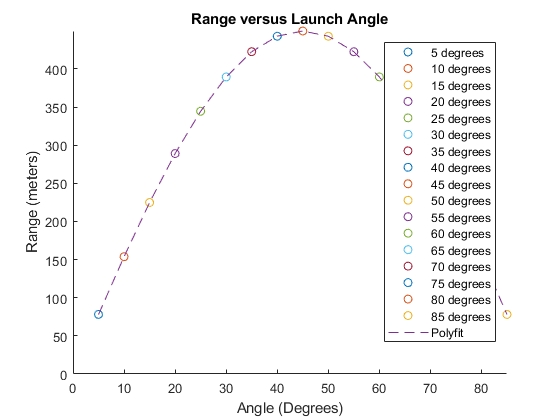

y1 = polyval(lobf,angleRange(1, :));

plot(angleRange(1, :), y1, "--");

legendData = string(angles) + " degrees";
legendData(length(legendData)+1) = "Polyfit";
legend(legendData);

We can also verify this mathematically:


$$V_{0y} = V_0 \sin \theta
\\
V_{y}(t)  = V_0  \sin \theta - gt
\\
\text{so peak is at } V_0 sin\theta = gt
\\ 
x = V_{0x} t = V_0 \cos\theta t
\\
t = \frac{x}{V_0 \cos\theta}
\\
x = \frac{V^2_0 \sin \theta \cos \theta}{g}
\\
2x = 2 \cdot \frac{V^2_0 \sin \theta \cos \theta}{g}
\\
x_{max} = \frac{V^2_0 \sin 2\theta }{g}
\\
\text{and } \sin 2\theta \text{ has a max at } 45^\text{o}$$


**Appendix 1**

function a=V_t(~,V)
    global gx; % acceleration of gravity in m-s^-2
    global gz; % acceleration of gravity in m-s^-2
    global xsec;
    global c;
    global rho;

    vx=V(1);
    vz=V(2);
    
    ax = gx - 1/2 * c * rho * xsec * sqrt(vx^2 + vz^2)*(vx);
    az = gz - 1/2 * c * rho * xsec * sqrt(vx^2 + vz^2)*(vz);
    a=[ax;az;vx;vz];
end

**Appendix 2**: 

function a=V_t_noresistance(~,V)
    global gx; % acceleration of gravity in m-s^-2
    global gz; % acceleration of gravity in m-s^-2

    vx=V(1);
    vz=V(2);
    
    ax = gx;
    az = gz;
    a=[ax;az;vx;vz];
end

**Appendix 3:**

The following function is used to terminate `ode45` calculation of a ballistic motion. 

function [value,isterminal,direction] = bounceEvents(~,y)
    value = y(4);     % Detect height = 0
    isterminal = 1;   % Stop the integration
    direction = -1;   % Terminate if negative direction
end

## End of script